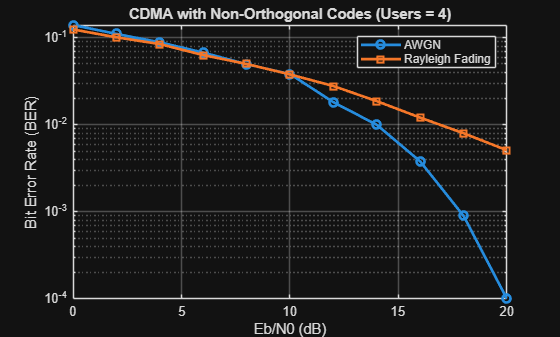

clc; clear; close all;

%% Parameters
numUsers = 4;          
N = 1e4;               
EbN0_dB = 0:2:20;
SF = 8;                % Spreading Factor

% Generate NON-orthogonal spreading codes
codes = randi([0 1], numUsers, SF);
codes = 2*codes - 1;   % Convert to ±1

% Normalize codes (important!)
for u = 1:numUsers
    codes(u,:) = codes(u,:) / norm(codes(u,:));
end

% Generate data
bits = randi([0 1], numUsers, N);
symbols = 2*bits - 1;   % BPSK

ber_awgn = zeros(size(EbN0_dB));
ber_rayleigh = zeros(size(EbN0_dB));

%% ================= Simulation =================
for i = 1:length(EbN0_dB)
    
    EbN0 = 10^(EbN0_dB(i)/10);
    noise_var = 1/(2*EbN0);
    
    err_awgn = 0;
    err_ray = 0;
    
    for k = 1:N
        
        %% -------- Transmit (multi-user superposition) --------
        tx = zeros(1, SF);
        
        for u = 1:numUsers
            tx = tx + symbols(u,k) * codes(u,:);
        end
        
        %% ================= AWGN =================
        noise = sqrt(noise_var)*randn(1, SF);
        rx_awgn = tx + noise;
        
        % Detect User 1
        decision = sum(rx_awgn .* codes(1,:));
        detected = sign(decision);
        if detected == 0, detected = 1; end
        
        if detected ~= symbols(1,k)
            err_awgn = err_awgn + 1;
        end
        
        %% ================= Rayleigh =================
        h = (randn + 1j*randn)/sqrt(2);
        rx_ray = h * tx + noise;
        
        % Equalization
        rx_eq = real(rx_ray / h);
        
        decision = sum(rx_eq .* codes(1,:));
        detected = sign(decision);
        if detected == 0, detected = 1; end
        
        if detected ~= symbols(1,k)
            err_ray = err_ray + 1;
        end
        
    end
    
    ber_awgn(i) = err_awgn / N;
    ber_rayleigh(i) = err_ray / N;
    
end

%% ================= Plot =================
figure;
semilogy(EbN0_dB, ber_awgn, 'o-', 'LineWidth', 2); hold on;
semilogy(EbN0_dB, ber_rayleigh, 's-', 'LineWidth', 2);

grid on;
xlabel('Eb/N0 (dB)');
ylabel('Bit Error Rate (BER)');
title(['CDMA with Non-Orthogonal Codes (Users = ', num2str(numUsers), ')']);
legend('AWGN','Rayleigh Fading');